# Route

clear;
close all;

%% Open the file browser dialog
[file_name, path_name] = uigetfile('*', 'Choose the .csv route file');

% Check if a file was selected
if isequal(file_name, 0) || isequal(path_name, 0)
    disp('No file selected.');
elseif ~contains(file_name, ".csv")
    disp(['Wrong data type. Received: ', file_name])
else
    % Display its full path
    full_path = fullfile(path_name, file_name);
    disp(['Selected File: ' full_path]);
end

Selected File: C:\Git_Repository\aCentauri\ss_offline_data\route\GunnPoint\route_gunn_point.csv



% Extract values from csv to a table
route_table = readtable(full_path);

% Assign the column values
longitude = route_table.longitude;
latitude = route_table.latitude;
cum_distance = route_table.cumDistance;
altitude = route_table.altitude;
altitude_smoothed = route_table.altitudeSmoothed;
max_speed = route_table.maxSpeed;
inclination = route_table.inclination;
inclination_smooth = route_table.inclinationSmooth;
inclination_smoothed = route_table.inclinationSmoothed;

## Plot

#### Inclination vs distance

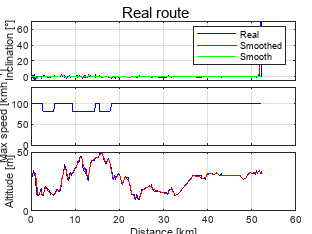

title = 'Real route';
synchronizeXAxes = true;
xaxis = cum_distance / 1000;
builder = VerticalPlotBuilder(synchronizeXAxes, title);

builder.addPlot(xaxis, rad2deg(inclination),'-','Color','b');
builder.addPlot(xaxis, rad2deg(inclination_smoothed),'-','Color','r');
builder.addPlot(xaxis, rad2deg(inclination_smooth),'-','Color','g');
builder.setYlabel("Inclination [°]");
builder.setLegend("Real", "Smoothed", "Smooth")

builder.startNewSubplot();
builder.addPlot(xaxis, max_speed,'-','Color','b');
builder.setYlabel('Max speed [kmh^{-1}]');
builder.setYlim([0 140]);

builder.startNewSubplot();
builder.addPlot(xaxis, altitude, '-', 'Color', 'b');
builder.addPlot(xaxis, altitude_smoothed, '-', 'Color', 'r');
builder.setYlabel('Altitude [m]');

builder.setXlabel('Distance [km]');
builder.drawNow()

#### Real route

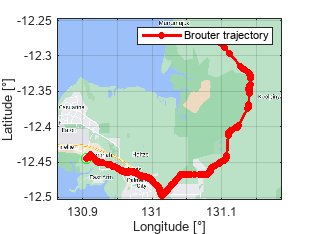

figure
hold on; box on; grid on
plotTrajectory(longitude, latitude, 'Brouter')
plotGeoMap()
clickableLegend()
xlabel('Longitude [°]')
ylabel('Latitude [°]')

function plotTrajectory(long, lat, name)

h = hggroup('DisplayName', sprintf('%s trajectory', name));
h.Annotation.LegendInformation.IconDisplayStyle = 'on';

plot(h, long(1), lat(1), 'go', 'DisplayName', sprintf('%s start', name), 'MarkerSize', 8)
plot(h, long(end), lat(end), 'bo', 'DisplayName', sprintf('%s finish', name), 'MarkerSize', 8)
plot(h, long, lat, 'Color', 'r', 'LineWidth', 2, 'Marker', '.', 'MarkerSize', 18, 'DisplayName', sprintf('%s trajectory', name))

end % function